% Load Data
load DAC_Linearity_Data.mat

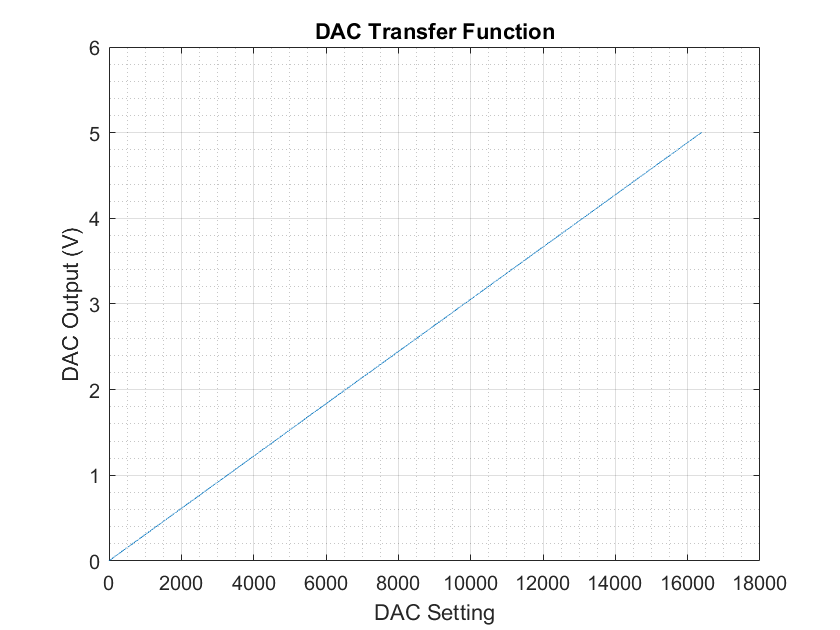

% Plot Transfer Function
figure()
plot(set_point,data);

title('DAC Transfer Function');
grid ON;
grid MINOR;
xlabel('DAC Setting');
ylabel('DAC Output (V)');

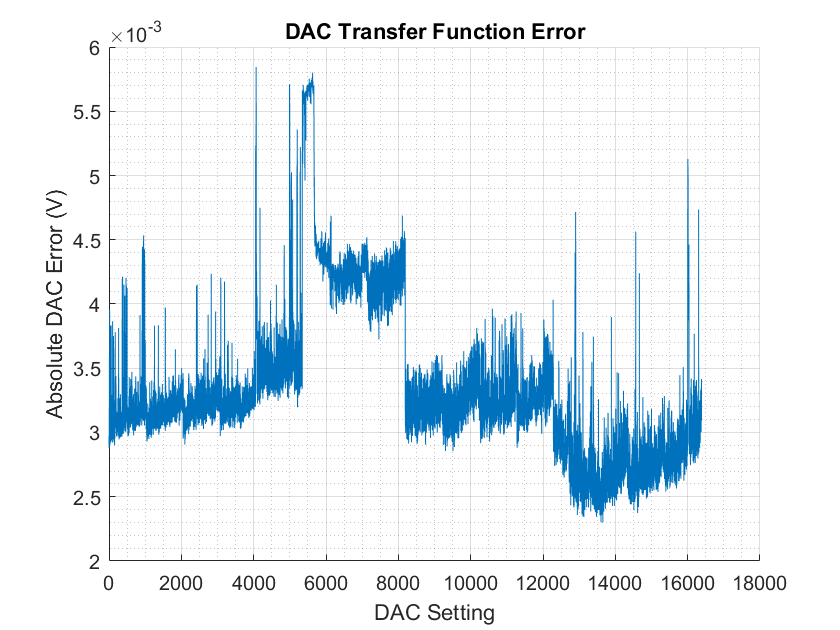

% Comparison to ideal transfer function
ideal_tf = double(set_point)*(5/(2^14-1));
ideal_tf = min(2^14-1,max(ideal_tf,0));

% Error
figure()
hold on;
plot(set_point,data-ideal_tf);
title('DAC Transfer Function Error');
grid ON;
grid MINOR;
xlabel('DAC Setting');
ylabel('Absolute DAC Error (V)');

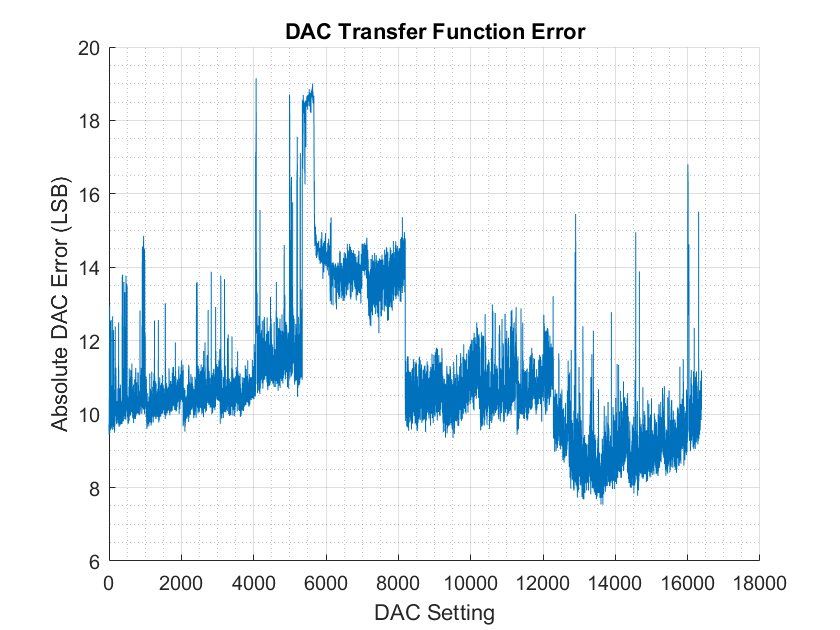


% Error
figure()
hold on;
plot(set_point,(data-ideal_tf)/(5/(2^14-1)));
title('DAC Transfer Function Error');
grid ON;
grid MINOR;
xlabel('DAC Setting');
ylabel('Absolute DAC Error (LSB)');